# Rasterising Exercises

Use the [modified Bresenham's algorithm](https://jonshiach.github.io/graphics-book/files/5.1_Drawing_lines.html?highlight=modified%20bresenham) to draw the lines joining points with the following co-ordinates:

(a) (2,2) and (7,5);

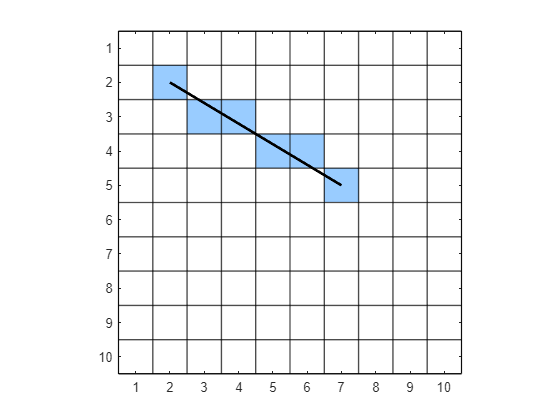

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Define endpoints
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
colour = [153 ; 204 ; 255] / 255;

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight
xticks(1:Nx)

(b) (8,3) and (5,8).

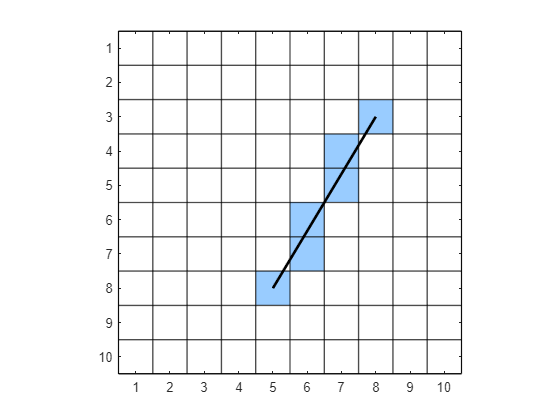

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Define endpoints
x0 = 8;
y0 = 3;
x1 = 5;
y1 = 8;
colour = [153 ; 204 ; 255] / 255;

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight
xticks(1:Nx)

### Exercise 27

Use the midpoint algorithm to calculate the positions of pixels on the first octant of a circle centred at $(11,11)$ with radius 9.

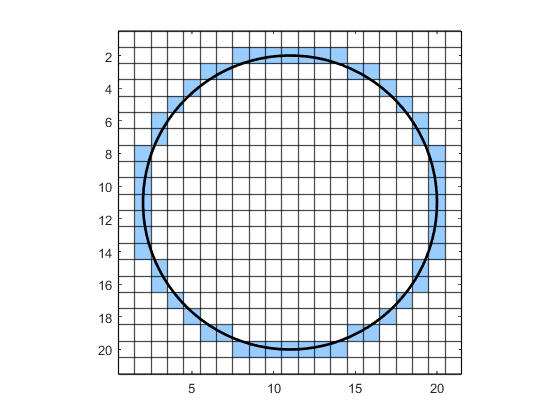

clear

% Define circle
cx = 11;
cy = 11;
r = 9;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 21;
Ny = 21;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = drawcircle(img, cx, cy, r, colour);

% Calculate circle
theta = linspace(0, 2 * pi, 100);
x = cx + r * cos(theta);
y = cy + r * sin(theta);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot(x, y, 'k', LineWidth=2)
hold off
axis equal tight

#### Exercise 28

The edges of a triangular polygon with vertices at the pixel co-ordinates $(6, 2)$, $(2, 6)$ and $(9, 9)$ have been rasterised resulting in the raster shown below. Using the starting pixel $(5,5)$, use the flood fill algorithm to fill the interior of the polygon where the target colour is white and the replacement colour is blue. Write out the queue at each step of the algorithm. 

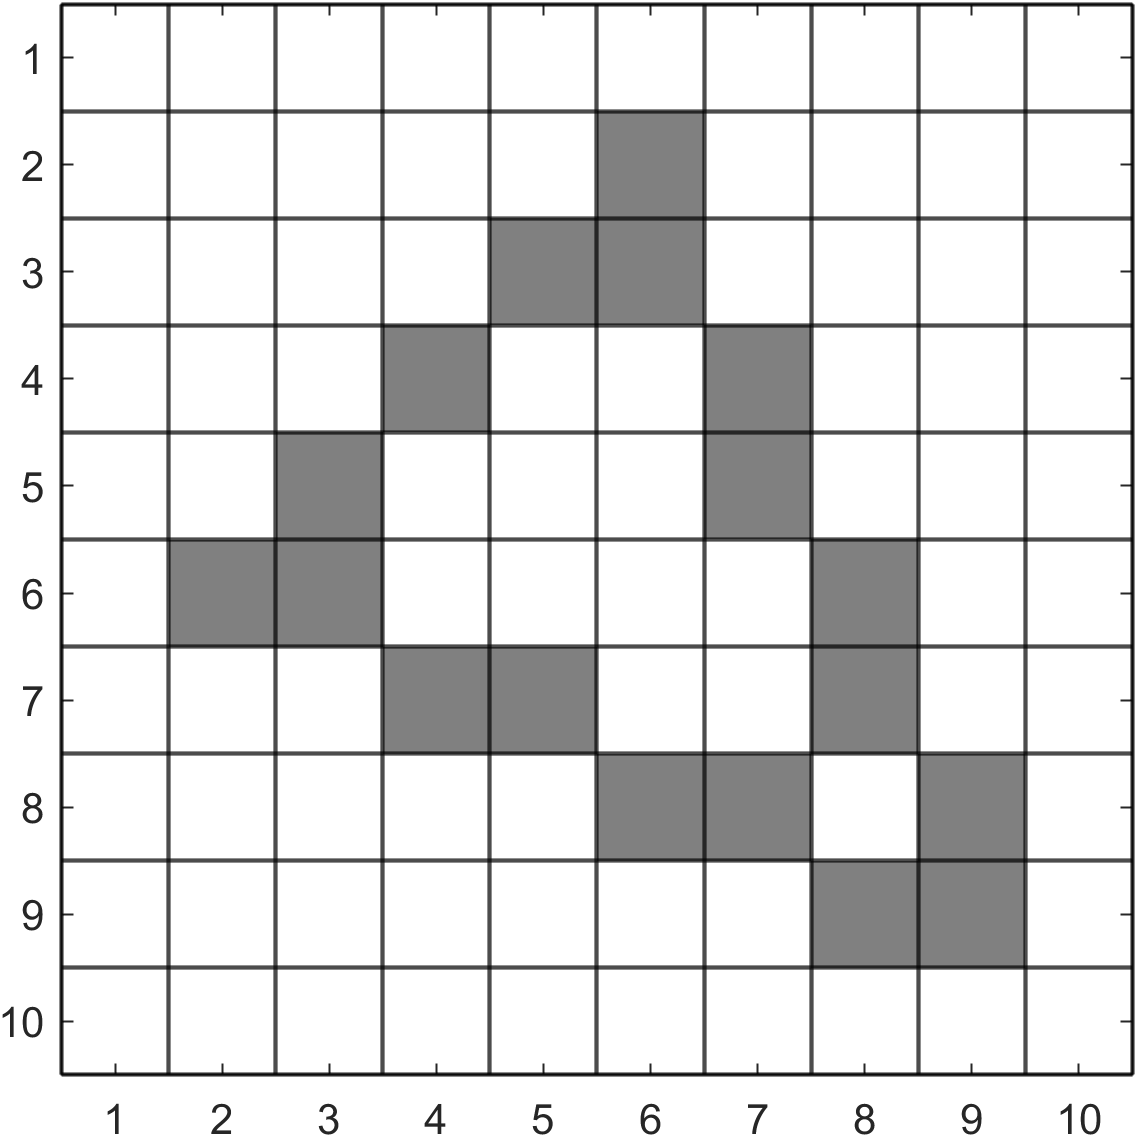

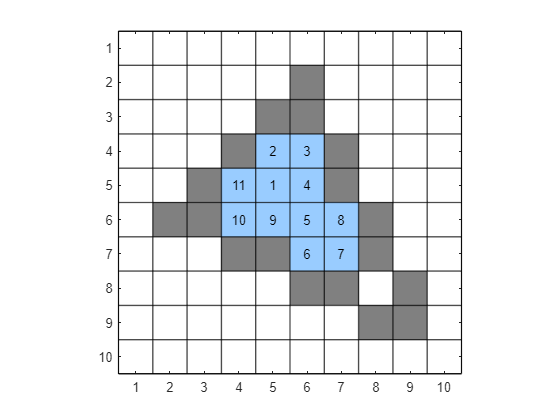

clear

% Define polygon
X = [6, 2, 9, 6];
Y = [2, 6, 9, 2];
border = [128 ; 128 ; 128] / 255;

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Draw polygon outline
j = length(X);
for i = 1 : length(X)
    img = drawline(img, X(i), Y(i), X(j), Y(j), border);
    j = i;
end

% Fill interior of polygon
x0 = 5;
y0 = 5;
target = [255 ; 255 ; 255];
replacement = [153 ; 204 ; 255] / 255;
[img, filled] = floodfill(img, x0, y0, target, replacement);

% Plot raster
figure
image(img)
pixelgrid(img)
for i = 1 : size(filled,1)
    text(filled(i,1), filled(i,2), sprintf("%1i",i), HorizontalAlignment='center')
end
xticks(1:Nx)
axis equal tight

### Example 29

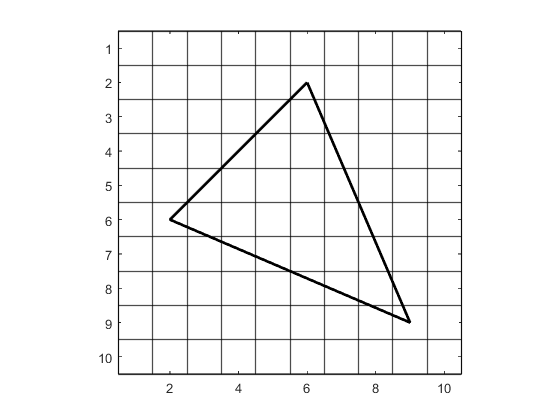

clear

% Define polygon
X = [6, 2, 9, 6];
Y = [2, 6, 9, 2];
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Draw polygon outline
% img = drawpolygon(img, X, Y, colour);

% Plot raster
image(img)
pixelgrid(img)
hold on
plot([X, X(1)], [Y, Y(1)], 'k-', LineWidth=2) 
hold off
axis equal tight

## Functions

Function to plot a grid of lines for the pixels

function pixelgrid(img)

[Ny, Nx, ~] = size(img);
for i = 1 : Ny + 1
    yline(i-0.5, Color='k', LineWidth=1)
end
for i = 1 : Nx + 1
    xline(i-0.5, Color='k', LineWidth=1)
end

end

### Bresenham's algorithm

function R = drawline(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = abs(x1 - x0);
dy = abs(y1 - y0);
d = 2 * dx - 2 * dy;
xstep = 1;
ystep = 1;
if x > x1
    xstep = -1;
end
if y > y1
    ystep = -1;
end

while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end

    dd = 0;
    if d >= -dy
        x = x + xstep;
        dd = dd - 2 * dy;
    end
    
    if d <= dx
        y = y + ystep;
        dd = dd + 2 * dx;
    end
    d = d + dd;
end

end

### Midpoint algorithm

function R = drawcircle(R, cx, cy, r, colour)

x = r;
y = 0;
d = 1 - r;
while x >= y
    R(cx + x,cy + y, :) = colour;
    R(cx + x,cy - y, :) = colour;
    R(cx - x,cy + y, :) = colour;
    R(cx - x,cy - y, :) = colour;
    R(cx + y,cy + x, :) = colour;
    R(cx + y,cy - x, :) = colour;
    R(cx - y,cy + x, :) = colour;
    R(cx - y,cy - x, :) = colour;

    if d <= 0
        d = d + 2 * y + 3;
    else
        d = d + 2 * y - 2 * x + 5;
        x = x - 1;
    end
    y = y + 1;
end

end

### Flood fill algorithm

function [R, filled] = floodfill(R, x0, y0, target, replacement)

Q = [x0, y0];
filled = [];
while isempty(Q) == 0
    x = Q(end,1);
    y = Q(end,2);
    Q(end, :) = [];
    if isequal([R(y,x,1) ; R(y,x,2) ; R(y,x,3)], target)
        R(y,x,:) = replacement;
        Q = [ Q ; x + 1, y ; x - 1, y ; x, y + 1 ; x, y - 1 ];
        filled = [filled ; x, y];
    end
end

end

### Scanline algorithm

function R = drawpolygon(R, X, Y, colour)

% Generate edge table
n = length(X);
ET = [];
for i = 1 : n
    j = 1 + mod(i, n);
    if Y(i) < Y(j)
        ET = [ET ; X(i), (X(j) - X(i)) / (Y(j) - Y(i)), Y(i), Y(j) ];
    elseif Y(i) > Y(j)
        ET = [ET ; X(j), (X(i) - X(j)) / (Y(i) - Y(j)), Y(j), Y(i) ];
    else
        continue
    end
end

% Loop through scanlines
y = min(Y);
AET = [];
while ~isempty(ET) || ~isempty(AET)
    
    % Move edges from ET to AET whose ymin = y
    i = 1;
    while i <= size(ET,1)
        if ET(i,3) == y
            AET = [ AET ; ET(i,[1,2,4]) ];
            ET(i,:) = [];
        else
            i = i + 1;
        end
    end

    % Sort AET by x value
    AET = sortrows(AET, 1);

    % Fill scanline
    i = 1;
    while i < size(AET,1)
        xL = ceil(round(AET(i,1),2));
        xR = floor(round(AET(i+1,1),2));
        if xL == xR
            R(y,xL,:) = colour;
            i = i + 1;
        else
            for x = xL : xR
                R(y,x,:) = colour;
            end
            i = i + 2;
        end
    end

    % Remove edges from AET whose ymax = y
    i = 1;
    while i <= size(AET,1)
        if AET(i,3) == y
            AET(i,:) = [];
        else
            i = i + 1;
        end 
    end

    % Add 1/m to x in AET
    AET(:,1) = AET(:,1) + AET(:,2);

    % Increment y
    y = y + 1;

end

end